# Decision Tree Classification

In this lab sheet we'll look at how to train and use a Decision Tree classifier using built-in Matlab functions. Prerequisites:

- **You need to: (i) have a copy of the iris.csv dataset (available on Moodle) saved in the same directory as this live script; (ii) set Matlab's Current Folder to point at that directory**;

- This script assumes you have completed the Matlab Fundamentals materials.

## Loading and preparing datasets

The following steps should all be familiar from the k-NN and Naive Bayes labs. Refer back to them if you're not sure about any of the steps

Read the iris dataset:

% read the iris dataset:
data = readtable('iris.csv');

Use it to create a testing dataset (25% of the data) and a training dataset (75% of the data):

% how many examples for 25%:
nTest = round(0.25 * size(data,1))

nTest = 38

% re-seed Matlab's random number generator:
rng(1)
% shuffle the data and create a testing dataset and a training dataset:
data_shuffled = data(randperm(size(data,1)), :);
data_test = data_shuffled(1:1:nTest, :);
size(data_test)

ans =     38     5


data_train = data_shuffled(nTest+1:1:end, :);
size(data_train)

ans =    112     5


% separate the examples and the labels for the testing dataset:
test_labels = categorical(data_test{:,'species'});
test_examples = data_test;
test_examples(:,'species') = [];
% separate the examples and the labels for the training dataset:
train_labels = categorical(data_train{:,'species'});
train_examples = data_train;
train_examples(:,'species') = [];

m =   ClassificationTree
           PredictorNames: {'sepal_length'  'sepal_width'  'petal_length'  'petal_width'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 112


  Properties, Methods


## Training a Decision Tree classifier

Now we have our data organised, we can train a Decision Tree classifier by calling Matlab's `fitctree()` function.

The input arguments to `fitctree()` are:

- `train_examples` - our table of training examples

- `train_labels` - our categorical array of associated class labels

- A name-value pair argument which says that we should not try to merge similar leaves during training

- A name-value pair argument which says that we should not try to prune the decision tree after training is complete

The output from the `fitctree()` function is:

- `m` - an object containing our trained model

m = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off')


Decision tree for classification
1  if petal_length<2.6 then node 2 elseif petal_length>=2.6 then node 3 else versicolor
2  class = setosa
3  if petal_width<1.75 then node 4 elseif petal_width>=1.75 then node 5 else versicolor
4  if petal_length<5.35 then node 6 elseif petal_length>=5.35 then node 7 else versicolor
5  if sepal_length<5.95 then node 8 elseif sepal_length>=5.95 then node 9 else virginica
6  class = versicolor
7  class = virginica
8  class = virginica
9  class = virginica



Having built a tree you can ask to see a text-based description of all the nodes it contains:

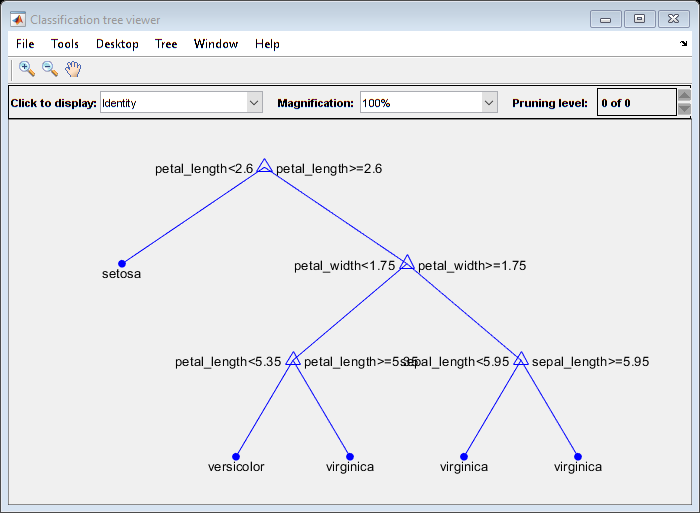

view(m);

It's also possible to see a graphical description. The following line has been left commented out as it pops up a new window (which can be annoying if you're re-running the script a lot) but you can uncomment it if you're interested:

%view(m, 'Mode', 'Graph')

## Use your trained classifier for prediction

Once you have trained your model, you can use it to classify new examples where you **don't** already know the value of the associated class label.

We'll try to classify the examples in our testing data. (In truth, we know the true class labels for these examples, but we won't pass them to the classifier, and we'll use them later on to measure how accurate the classifier's predictions were.)

To predict class labels for our testing examples based only on the features they contain we call Matlab's `predict()` function.

The input arguments to `predict()` are:

- `m` - the trained model we want to use to make the predictions

- `test_examples` - our table of testing examples

The output from `predict()` is:

- `predictions` - an array of predicted class labels; one for each example (row) in the table `test_examples`

% use our trained Decision Tree classifier to classify the testing data:
predictions = predict(m, test_examples);

## Evaluating the classifier's Performance

Let's evaluate the classifier's performance by generating a confusion matrix:

% output a confusion matrix:

c =     12     0     0
     0    10     0
     0     3    13


order = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


[c,order] = confusionmat(test_labels, predictions)

And let's use the values in the confusion matrix to compute the overall classification accuracy:

% calculate the overall classification accuracy:

p = 0.9211

p = sum(diag(c)) / sum(c(1:1:end))

Check you can correctly interpret the values in the confusion matrix by completing the following questions without looking back at your answers in previous labs... Use the sliders to select your answers:

% how many setosa irises are there in the testing data?

ans = 12

12
% how many of those setosa irises are correctly classified?

ans = 12

12
% how many versicolor irises are there in the testing data?

ans = 13

13
% how many of those versicolor irises are incorrectly classified as being virginica irises?

ans = 3

3
% how many virginica irises are there in the testing data?

ans = 13

13
% how many of those virginica irises are incorrectly classified as being versicolor irises?

ans = 0

0

n_test = 142

## Tasks

Try training and testing a Decision Tree classifier using the "wisc_bc_data.csv" dataset you used in the Matlab fundamentals materials. You'll need to work through the steps below, and you can copy and paste code from the sections above (or previous weeks) to help you with each one. Before you do, why not see if you can remember how to do the steps for yourself - you've now performed each of them multiple times and hopefully they are becoming familiar:

- Load up the dataset

- Shuffle the dataset and separate it into training data and testing data

- Separate out the class labels in both your training data and testing data

- Train the classifier with your training data

- Test the classifier on your testing data

- Evaluate the classifier's performance by computing a confusion matrix

- Compute the overall proportion of correct classifications

% write your code on the lines below
df = readtable('wisc_bc_data.csv');


ans =    142    32


% shuffle dataset and split into training and testing data
n_test = round(0.25 * size(df, 1))

ans =    427    32


rng(1)
df_shuffled = df(randperm(size(df, 1)), :);
df_test = df_shuffled(1:1:n_test, :);
size(df_test)
df_train = df_shuffled(n_test+1:1:end, :);
size(df_train)

% seperate the examples from the labels in the testing set
df_test_labels = categorical(df_test{:, 'diagnosis'});
df_test_examples = df_test;
df_test_examples(:, 'diagnosis') = [];

% separate the example from the labels in the training set
df_train_labels = categorical(df_train{:, 'diagnosis'});


Decision tree for classification
 1  if area_worst<884.75 then node 2 elseif area_worst>=884.75 then node 3 else Benign
 2  if concavePoints_worst<0.1358 then node 4 elseif concavePoints_worst>=0.1358 then node 5 else Benign
 3  if concavity_mean<0.062425 then node 6 elseif concavity_mean>=0.062425 then node 7 else Malignant
 4  if radius_worst<16.805 then node 8 elseif radius_worst>=16.805 then node 9 else Benign
 5  if texture_mean<20.3 then node 10 elseif texture_mean>=20.3 then node 11 else Malignant
 6  if texture_mean<19.545 then node 12 elseif texture_mean>=19.545 then node 13 else Malignant
 7  class = Malignant
 8  if area_worst<785.75 then node 14 elseif area_worst>=785.75 then node 15 else Benign
 9  class = Benign
10  if area_worst<811.1 then node 16 elseif area_worst>=811.1 then node 17 else Benign
11  class = Malignant
12  class = Benign
13  class = Malignant
14  class = Benign
15  if radius_worst<16.215 then node 18 elseif radius_worst>=16.215 then node 19 else Benign
1

df_train_examples = df_train;
df_train_examples(:, 'diagnosis') = [];

% train the classifier
model = fitctree(df_train_examples, df_train_labels, 'MergeLeaves','off', 'Prune','off');
view(model)
%view(model, 'Mode', 'Graph')

c =     82     3
     5    52


order = 2×1 categorical array
     Benign 
     Malignant 



% test the classifier model on the testing data
model_predictions = predict(model, df_test_examples);

accuracy = 0.9437


% evaluate classifier's performance using confusion matrix
[c,order] = confusionmat(df_test_labels, model_predictions)

models = 1×3 categorical array
     k-NN(k=15)      Naive Bayes      Decision Tree 


model_accuracy =     0.9648    0.9577    0.9437


% compute classifier accuracy
accuracy = sum(diag(c)) / sum(c(1:1:end))

You now have overall classification accuracies for three different classifiers on the "wisc_bc_data.csv" dataset. Create a bar graph to display the three results side-by-side. You should give your graph a title and label both the axes:

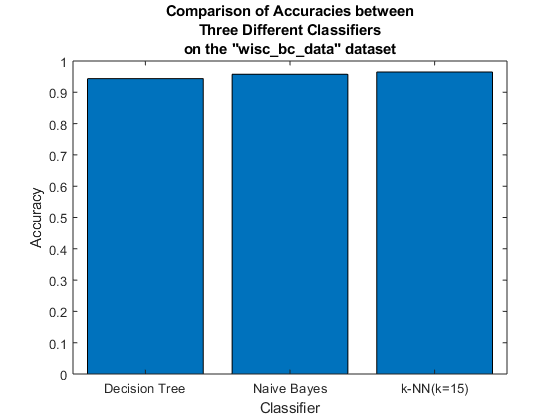

% type your solution on the line below:
models = categorical({'k-NN(k=15)', 'Naive Bayes', 'Decision Tree'})

model_accuracy = [0.9648,0.9577,0.9437]
fig = figure;
bar(models, model_accuracy)
title({'Comparison of Accuracies between'; 'Three Different Classifiers'; 'on the "wisc_bc_data" dataset'}, 'Interpreter', 'none');
xlabel('Classifier');
ylabel('Accuracy');

Use the `xticklabels()` function to put string labels (e.g., 'k-NN (k=15)', 'Naive Bayes', 'Decision Tree') on the ticks along the x-axis. You can call `help xticklabels` from the Command Window to find out exactly how to call it:

% type your solution on the line below:

